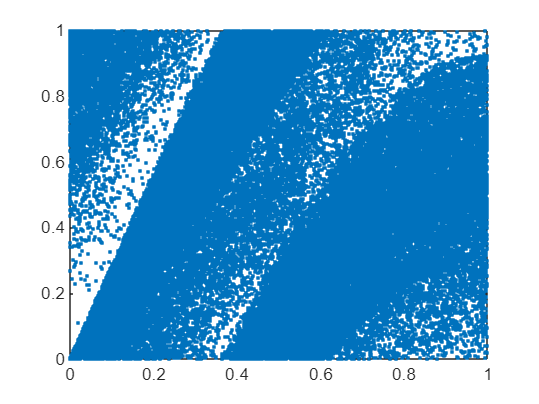

dx=zeros(1,65536);
dy=zeros(1,65536);
hx=zeros(1,65536);
hy=zeros(1,65536);
h1=zeros(1,65536);
h2=zeros(1,65536);
l1=[2.46,2.82,2.64,2.72,2.88,2.92,2.59,2.33];
    =[0.11,0.23,0.32,0.45,0.78,0.83,0.95,0.59];
prime=[7,11,13,17,19,23,29,31];
dx(1)=0.72;
dy(1)=0.64;
hx(1)=0.32;
hy(1)=0.72;
ha=1.4;
hb=0.3;
a=2.75;
b=0.2;
secretkey="";
for i=1:65536
        dx(i+1)=mod(dy(i),1);
        dy(i+1)=mod((-b*dx(i))+(a*dy(i))-(power(dy(i),3)),1);
        hx(i+1)=mod((1-ha*pow2(hx(i))+hy(i)),1);
        hy(i+1)=hb*hx(i);
         n=1;
         m=32;
         d2b=""+fix(rem(hx(i)*pow2(-(n-1):m),2));
         b2d=""+fix(rem(hy(i)*pow2(-(n-1):m),2));
         binarystring1="";
         binarystring2= "";
         for j=1:length(prime)
         binarystring1= binarystring1+d2b(prime(j));
         binarystring2= binarystring2+b2d(prime(j));
         end
         pos1=mod(bin2dec(binarystring1),8);
         pos2=mod(bin2dec(binarystring2),8);
         if pos1==0 || pos2==0
         a=l1(4);
         b=l2(4);
         else
         a=l1(pos1);
         b=l2(pos2);
         end
         h1(i)=pos1;
         h2(i)=pos2;
         n=1;
         m=32;
         d2b=""+fix(rem(dx(i)*pow2(-(n-1):m),2));
        for j=24:32
        secretkey=secretkey+d2b(j);
        end
end

plot(dx,dy,'.');